# Laboratorio 2 - Modelo Geométrico Inverso

Andrés Felipe Medina Medina - Juan Santana Salgado - Osmar Toloza Bernal

## 3. Modelo Geométrico Inverso

### 3.1. Desarrollo del modelo geométrico inverso

Para el desarrollo de la cinemática inversa del robot ABB IRB2400, es pertinente emplear el método de desacople cinemático. 

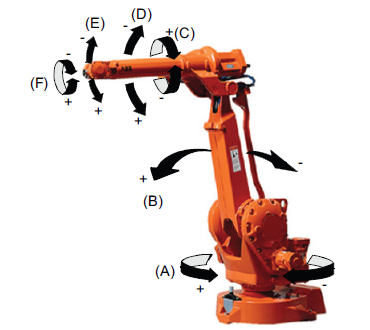

*Fig.1. Diagrama de articulaciones - ABB IRB2400.*

A partir de la figura 1, se observa que las articulaciones A, B y D se encargan de posicionar al efector final en un punto en el espacio euclídeo; mientras que C, E y F se encargan de generar una orientación determinada del mismo. Por tanto, para resolver la posición del efector final, se trabajará con los parámetros $q_1,q_2$ y $q_3$, correspondientes a las articulaciones A, B y D. Para la resolución de la orientación, se encontrarán los parámetros $q_4,q_5$ y $q_6$, que corresponden a las articulaciones C, E y F.

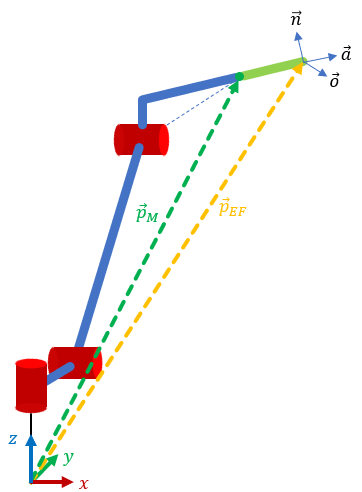

*Fig.2. Método de desacople cinemático - ABB IRB2400.*

Para el análisis que se presenta, todas las medidas están dadas en milímetros.

#### 3.1.1. Posición del efector final

Para esta primera sección, se trabajará con la posición de la muñeca $\vec{p_M}=(x_M,y_M,z_M)$ del manipulador. Ésta se obtiene a partir de la posición $\vec{p_{EE}}=(x,y,z)$ del efector final mediante la expresión:


$$(x_M,y_M,z_M)=(x,y,z)-L\hat{a}$$


en donde $L=85$mm y $\hat{a}$ corresponde al vector de aproximación de la trama NOA asignada al efector final.

**Configuración 1:**

El análisis se inicia a partir del siguiente esquema:

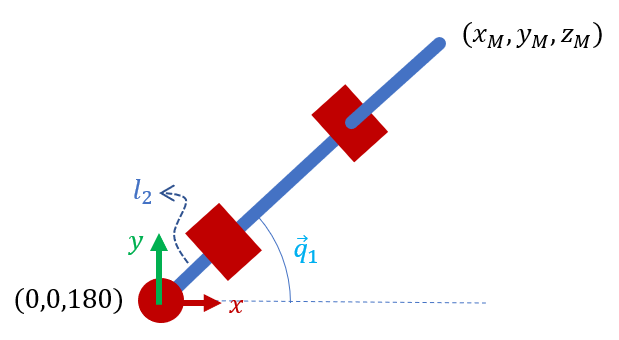

Desde el plano $xy$, se encuentra que:


$$\tan{(q_1)}=\frac{y_M}{x_M}$$



$$q_1=atan2(y_M,x_M)$$


A partir de la hoja de especificaciones, se sabe que $l_1=615$mm, $l_2=100$mm, $l_3=705$mm, y que $l_4=\sqrt{135^2+755^2}$mm. De igual manera, se encuentra que las coordenadas del punto $H$ (Fig.4) están dadas por $(l_2\cos{(q_1)},l_2\sin{(q_1)},l_1)$. 

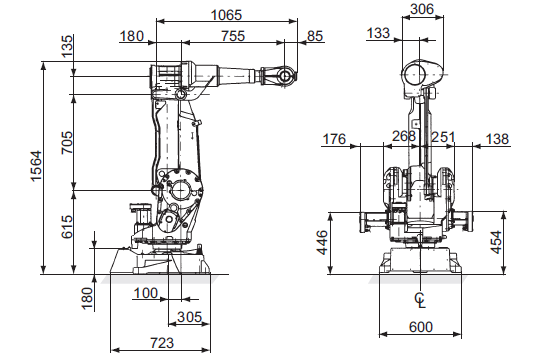

*Fig.3. Dimensiones - ABB IRB2400.*

Ahora, estudiando el manipulador desde el plano $xz$:

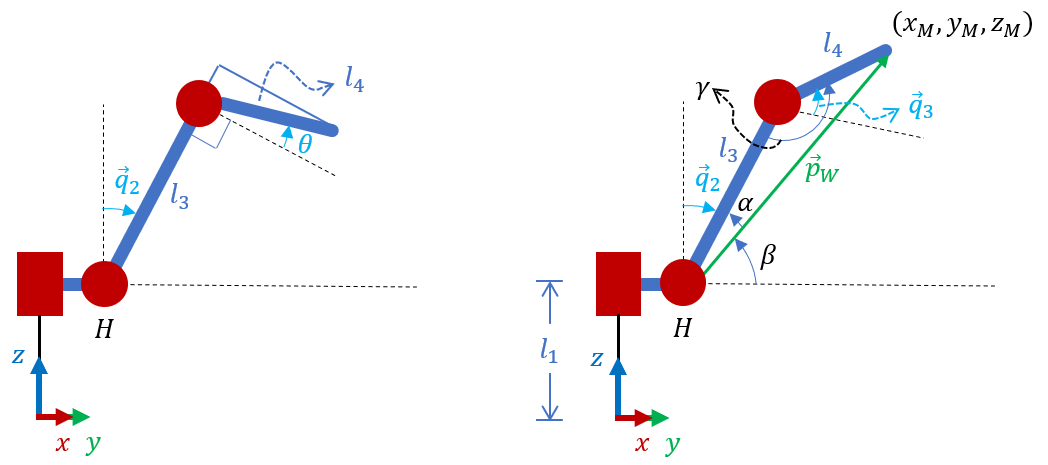

*Fig.4. Cinemática inversa por método geométrico - ABB IRB2400.*

Para la estimación de $q_2$ y $q_3$ se procede a aplicar la ley del coseno sobre el triángulo definido por $l_3,l_4$ y $p_W$. Se tiene que $p_W=\sqrt{(x_M-l_2\cos{(q_1)})^2+(y_M-l_2\sin{(q_1)})^2+(z_M-l_1)^2}$

Para empezar, se calcula $\alpha$:


$$l_4^2=l_3^2+p_W^2-2l_3p_W\cos{\alpha}$$



$$\cos{\alpha}=\frac{l_3^2+p_W^2-l_4^2}{2l_3p_W}$$


A partir de ello se sabe que $\sin{\alpha}=\pm \sqrt{1-(\cos{\alpha})^2}$. Por tanto:


$$\tan{\alpha}=\frac{\sin{\alpha}}{\cos{\alpha}}$$



$$\alpha=atan2(\sin{\alpha},\cos{\alpha})$$


Ahora, $\beta$ se puede calcular de la siguiente manera:


$$\sin{\beta}=\frac{z_M-l_1}{p_W}$$


de lo anterior se desprende que $\cos{\beta}=\pm \sqrt{1-(\sin{\beta})^2}$. Entonces:


$$\tan{\beta}=\frac{\sin{\beta}}{\cos{\beta}}$$



$$\beta=atan2(\sin{\beta},\cos{\beta})$$


De la figura 4 se observa que $q_2=\alpha+\beta$. Según esto, $q_2=atan2(\sin{\alpha},\cos{\alpha})+atan2(\sin{\beta},\cos{\beta})$.

Para la estimación de $q_3$ se aplica nuevamente la ley del coseno, esta vez para calcular $\gamma$:


$$p_W^2=l_3^2+l_4^2-2l_3l_4\cos{\gamma}$$



$$\cos{\gamma}=\frac{l_3^2+l_4^2-p_W^2}{2l_3l_4}$$


Se entiende que $\sin{\gamma}=\pm \sqrt{1-(\cos{\gamma})^2}$. Según esto:


$$\tan{\gamma}=\frac{\sin{\gamma}}{\cos{\gamma}}$$



$$\gamma=atan2(\sin{\gamma},\cos{\gamma})$$


Ahora bien, la ilustración a la izquierda de la figura 4 representa la posición *Home* del manipulador. El valor de $\theta$ se calcula a partir de las dimensiones provistas en la figura 3:


$$\theta=atan\left(\frac{135}{755}\right)$$


Considerando lo anterior, se concluye que $\gamma=90°+\theta+q_3$, Por lo que $q_3=\gamma-90°-\theta$:


$$q_3=atan2(\sin{\gamma},\cos{\gamma})-90°-atan\left(\frac{135}{755}\right)$$


**Configuración 2:**

La segunda configuración se ilustra en la siguiente figura:

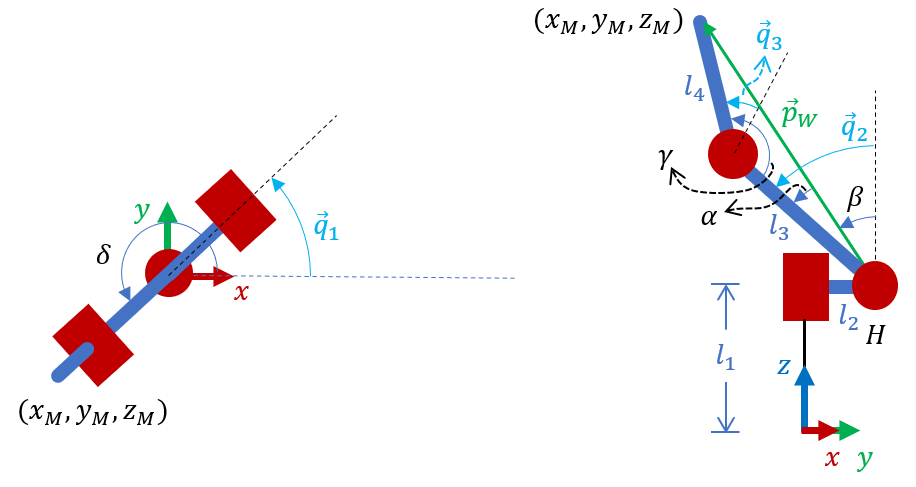

Para este caso, la expresión encontrada para $q_1$ ya no e válida. En su lugar, se observa que:


$$\delta=atan2(y_M,x_M)$$


Así mismo, se tiene que $q_1 =\delta -180°$. Entonces:


$$q_1=atan2(y_M,x_M)-180°$$


Respecto a $q_2$, se calculan primero las coordenadas del punto $H$, que están dadas por $(l_2\cos{(q_1)},l_2\sin{(q_1)},l_1)$. A partir de esto, se calcula $p_W$:


$$p_W=\sqrt{(x_M-l_2\cos{(q_1)})^2+(y_M-l_2\sin{(q_1)})^2+(z_M-l_1)^2}$$


A partir de la figura, se observa que:


$$\cos{\beta}=\frac{z_M-l_1}{p_W}$$


$\sin{\beta}=\pm \sqrt{1-(\cos{\beta})^2}$. 


$$\tan{\beta}=\frac{\sin{\beta}}{\cos{\beta}}$$



$$\beta=atan2(\sin{\beta},\cos{\beta})$$


Con relación a $\alpha$, se obtiene a partir de la ley del coseno. Con un procedimiento análogo al realizado en la configuración 1, se obtiene:


$$\cos{\alpha}=\frac{l_3^2+p_W^2-l_4^2}{2l_3p_W}$$



$$\sin{\alpha}=\pm \sqrt{1-(\cos{\alpha})^2}$$



$$\tan{\alpha}=\frac{\sin{\alpha}}{\cos{\alpha}}$$



$$\alpha=atan2(\sin{\alpha},\cos{\alpha})$$


Según lo anterior, se encuentra que $q_2=\alpha+\beta$.

Ahora, para estimar $q_3$ se procede a calcular $\gamma$ a través de la ley del coseno, obteniéndose:


$$\cos{\gamma}=\frac{l_3^2+l_4^2-p_W^2}{2l_3l_4}$$



$$\sin{\gamma}=\pm \sqrt{1-(\cos{\gamma})^2}$$


Por ende, $\gamma=atan2(\sin{\gamma},\cos{\gamma})$. Ahora, al igual que se definió en la configuración 1, $\theta$ es constante y viene dada por $\theta=atan\left(\frac{135}{755}\right)$.

Así pues, se tiene que $q_3=\gamma-(90°+\theta)$.

#### 3.1.2. Orientación del efector final

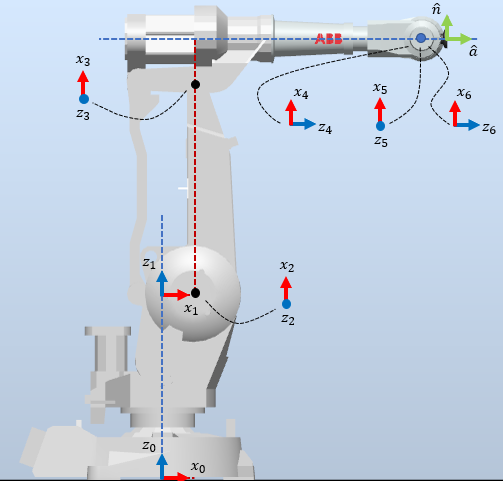

*Fig.5. Asignación de tramas - ABB IRB2400.*

Para resolver la orientación del efector final, se conoce la matriz de rotación $^0R_{ef}=[\hat{n}~\hat{o}~\hat{a}]$ que indica la orientación del mismo respecto a la trama base. Ahora bien, a partir de la figura 5, se observa que las tramas de la articulación 6 y la del efector final exhiben la misma orientación respecto a la trama base, por lo que no se requiere de una matriz de rotación adicional que describa la relación entre la trama {6} y la trama del efector final; es decir, $^0R_6~=~^0R_{ef}$.

Habiéndose calculado los valores requeridos para $q_1,q_2$ y $q_3$, se procede a resolver para $q_4,q_5$ y $q_6$ de la siguiente forma:


$$^0R_6~=~^0R_3~^3R_6~=~^0R_1~^1R_2~^2R_3~^3R_4~^4R_5~^5R_6$$


Dado que se conocen los valores de $q_1,q_2$ y $q_3$, es posible encontrar $^0R_3~=~^0R_1~^1R_2~^2R_3$. Posteriormente:


$$(^0R_3)^{-1}~^0R_6~=~^3R_4~^4R_5~^5R_6$$


Sea $R=(^0R_3)^{-1}~^0R_6$ una matriz de rotación cuyas entradas son conocidas. Entonces:


$$R=~^3R_4~^4R_5~^5R_6$$


Ahora, a partir de la asignación de tramas propuesta en la figura 5, se calcula la tabla de parámetros DH para el manipulador en cuestión:

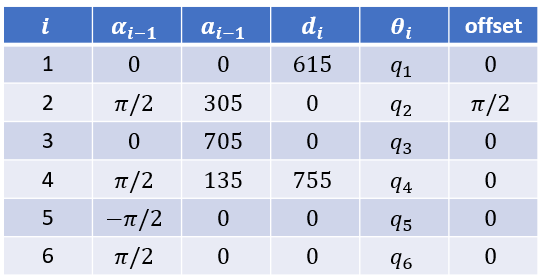

Con el fin de obtener la estructura de las matrices de rotación correspondientes a $^3R_4,^4R_5$ y $^5R_6$, se crea el robot y se recurre a la función $A$ disponible en el Toolbox de Peter Corke:

%Parámetros del manipulador - dm
l1=6.15;
l2=1.00;
l3=7.05;
l4=sqrt(1.35^2+7.55^2);
l5=0.85;

%Creación del robot
L(1)=Link([0 l1 0 0],'modified');
L(2)=Link([0 0 l2 pi/2],'modified');
L(2).offset=pi/2;
L(3)=Link([0 0 l3 0],'modified');
L(4)=Link([0 7.55 1.35 pi/2],'modified');
L(5)=Link([0 0 0 -pi/2],'modified');
L(6)=Link([0 0 0 pi/2],'modified');

irb2400=SerialLink(L,'name','ABB IRB2400')

 
irb2400 = 
 
ABB IRB2400 (6 axis, RRRRRR, modDH, fastRNE)                     
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|       6.15|          0|          0|          0|
|  2|         q2|          0|          1|      1.571|      1.571|
|  3|         q3|          0|       7.05|          0|          0|
|  4|         q4|       7.55|       1.35|      1.571|          0|
|  5|         q5|          0|          0|     -1.571|          0|
|  6|         q6|          0|          0|      1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0          

syms q4 q5 q6
th=1e-10;
T34=mapSymType(L(4).A(q4),'rational',@(x) piecewise(abs(x)<=th,0,x))

$$T34 = \left(\begin{array}{cccc} \cos\left(q_{4}\right) & -\sin\left(q_{4}\right) & 0 & \frac{27}{20}\\ 0 & 0 & -1 & -\frac{151}{20}\\ \sin\left(q_{4}\right) & \cos\left(q_{4}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T45=mapSymType(L(5).A(q5),'rational',@(x) piecewise(abs(x)<=th,0,x))

$$T45 = \left(\begin{array}{cccc} \cos\left(q_{5}\right) & -\sin\left(q_{5}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ -\sin\left(q_{5}\right) & -\cos\left(q_{5}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T56=mapSymType(L(6).A(q6),'rational',@(x) piecewise(abs(x)<=th,0,x))

$$T56 = \left(\begin{array}{cccc} \cos\left(q_{6}\right) & -\sin\left(q_{6}\right) & 0 & 0\\ 0 & 0 & -1 & 0\\ \sin\left(q_{6}\right) & \cos\left(q_{6}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Según estos resultados, se tiene que:


$$R=$$

$$\left\lbrack \begin{array}{ccc}
{\textrm{cq}}_4  & -{\textrm{sq}}_4  & 0\\
0 & 0 & -1\\
{\textrm{sq}}_4  & {\textrm{cq}}_4  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
{\textrm{cq}}_5  & -{\textrm{sq}}_5  & 0\\
0 & 0 & 1\\
-{\textrm{sq}}_5  & -{\textrm{cq}}_5  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
{\textrm{cq}}_6  & -{\textrm{sq}}_6  & 0\\
0 & 0 & -1\\
{\textrm{sq}}_6  & {\textrm{cq}}_6  & 0
\end{array}\right\rbrack$$



$$\begin{array}{l}
{\left\lbrack \begin{array}{ccc}
{\textrm{cq}}_4  & -{\textrm{sq}}_4  & 0\\
0 & 0 & -1\\
{\textrm{sq}}_4  & {\textrm{cq}}_4  & 0
\end{array}\right\rbrack }^{-1} \left\lbrack \begin{array}{ccc}
r_{11}  & r_{12}  & r_{13} \\
r_{21}  & r_{22}  & r_{23} \\
r_{31}  & r_{32}  & r_{33} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
{\textrm{cq}}_5  & -{\textrm{sq}}_5  & 0\\
0 & 0 & 1\\
-{\textrm{sq}}_5  & -{\textrm{cq}}_5  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
{\textrm{cq}}_6  & -{\textrm{sq}}_6  & 0\\
0 & 0 & -1\\
{\textrm{sq}}_6  & {\textrm{cq}}_6  & 0
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{ccc}
{\textrm{cq}}_4  & 0 & {\textrm{sq}}_4 \\
-{\textrm{sq}}_4  & 0 & {\textrm{cq}}_4 \\
0 & -1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
r_{11}  & r_{12}  & r_{13} \\
r_{21}  & r_{22}  & r_{23} \\
r_{31}  & r_{32}  & r_{33} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
{\textrm{cq}}_5  & -{\textrm{sq}}_5  & 0\\
0 & 0 & 1\\
-{\textrm{sq}}_5  & -{\textrm{cq}}_5  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
{\textrm{cq}}_6  & -{\textrm{sq}}_6  & 0\\
0 & 0 & -1\\
{\textrm{sq}}_6  & {\textrm{cq}}_6  & 0
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{ccc}
{\textrm{cq}}_4 r_{11} +{\textrm{sq}}_4 r_{31}  & {\textrm{cq}}_4 r_{12} +{\textrm{sq}}_4 r_{32}  & {\textrm{cq}}_4 r_{13} +{\textrm{sq}}_4 r_{33} \\
-{\textrm{sq}}_4 r_{11} +{\textrm{cq}}_4 r_{31}  & -{\textrm{sq}}_4 r_{12} +{\textrm{cq}}_4 r_{32}  & -{\textrm{sq}}_4 r_{13} +{\textrm{cq}}_4 r_{33} \\
-r_{21}  & -r_{22}  & -r_{23} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
{\textrm{cq}}_5 {\textrm{cq}}_6  & -{\textrm{cq}}_5 {\textrm{sq}}_6  & {\textrm{sq}}_5 \\
{\textrm{sq}}_6  & {\textrm{cq}}_6  & 0\\
-{\textrm{sq}}_5 {\textrm{cq}}_6  & {\textrm{sq}}_5 {\textrm{sq}}_6  & {\textrm{cq}}_5 
\end{array}\right\rbrack 
\end{array}$$


Igualando las entradas 2,3:


$$\begin{array}{l}
-{\textrm{sq}}_4 r_{13} +{\textrm{cq}}_4 r_{33} =0\\
{\textrm{sq}}_4 r_{13} ={\textrm{cq}}_4 r_{33} \\
\tan \left(q_4 \right)=\frac{r_{33} }{r_{13} }\\
{\mathit{\mathbf{q}}}_4 =\textrm{atan2}\left({\mathit{\mathbf{r}}}_{33} ,{\mathit{\mathbf{r}}}_{13} \right)
\end{array}$$


Ahora, igualando las entradas 1,3 y 3,3:


$$\begin{array}{l}
{\textrm{cq}}_4 r_{13} +{\textrm{sq}}_4 r_{33} ={\textrm{sq}}_5 \\
-r_{23} ={\textrm{cq}}_5 \\
\tan \left(q_5 \right)=\frac{{\textrm{cq}}_4 r_{13} +{\textrm{sq}}_4 r_{33} }{-r_{23} }\\
{\mathit{\mathbf{q}}}_5 =\textrm{atan2}\left({\textrm{cq}}_4 {\mathit{\mathbf{r}}}_{13} +{\textrm{sq}}_4 {\mathit{\mathbf{r}}}_{33} ,-{\mathit{\mathbf{r}}}_{23} \right)
\end{array}$$


Finalmente, igualando las entradas 2,1 y 2,2:


$$\begin{array}{l}
-{\textrm{sq}}_4 r_{11} +{\textrm{cq}}_4 r_{31} ={\textrm{sq}}_6 \\
-{\textrm{sq}}_4 r_{12} +{\textrm{cq}}_4 r_{32} ={\textrm{cq}}_6 \\
\tan \left(q_6 \right)=\frac{-{\textrm{sq}}_4 r_{11} +{\textrm{cq}}_4 r_{31} }{-{\textrm{sq}}_4 r_{12} +{\textrm{cq}}_4 r_{32} }\\
{\mathit{\mathbf{q}}}_6 =\textrm{atan2}\left(-{\textrm{sq}}_4 {\mathit{\mathbf{r}}}_{11} +{\textrm{cq}}_4 {\mathit{\mathbf{r}}}_{31} ,-{\textrm{sq}}_4 {\mathit{\mathbf{r}}}_{12} +{\textrm{cq}}_4 {\mathit{\mathbf{r}}}_{32} \right)
\end{array}$$


### 3.2. Multiplicidad de soluciones

Al observar la tabla de parámetros DH, se encuentra que solamente $a_5=0$. Así mismo, $a_3\neq 0$, lo cual nos indica que el criterio para estimar una cota máxima para el número de soluciones del problema cinemático inverso propuesto en el libro Robótica (Craig, John J.) no es la mejor aproximación para el problema en cuestión.

Para estimar la multiplicidad de soluciones, se analizarán las soluciones posibles una a una. Dando inicio al análisis con $q_1$, se observa que su cálculo arroja una única solución, puesto que depende de la posición en el espacio de la muñeca en el plano $xy$, la cual está dada por dos valores únicos $x_M$ y $y_M$.

En el caso de $q_2$, se sabe que $q_2=\alpha+\beta$. Dado que $\sin{\alpha}$ y $\cos{\beta}$ están definidos como raíces positivas o negativas, se entiende que, para cada ángulo, hay un total de 2 soluciones.

Puesto que $q_2$ depende de ambos ángulos, se concluye que puede tener un total de 4 posibles soluciones.

Respecto a $q_3$, se encontró que su cálculo depende de los ángulos $\gamma$ y $\theta$ (éste último, con valor constante). Dado que $\sin{\gamma}$ también está definido como una raíz positiva o negativa, este ángulo presenta dos posibles soluciones. Por ende, $q_3$ exhibirá también dos soluciones posibles. 

De acuerdo con lo anterior, se contaría con un total de $4\times2=8$ posibles soluciones. No obstante, se deben considerar los límites articulares. En particular, las limitaciones que presenta la articulación 3 (eje D) impiden que, por ejemplo, los ángulos $\alpha$ y $\beta$ sean negativos al mismo tiempo, puesto que generarían una configuración codo abajo frente a la cual la articulación 3 no posee un rango de barrido lo suficientemente amplio como para alcanzar el punto deseado en el espacio. Una excepción del mismo tipo ocurrirá para ángulos $\alpha$ y $\beta$ excesivamente positivos (se violarían los límites articulares de $q_2$ y, dependiendo del caso, también de $q_3$).

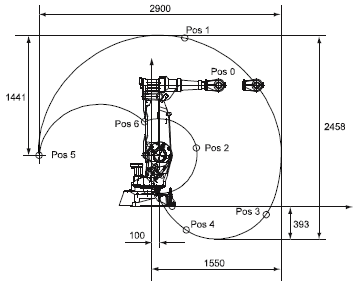

*Fig.6. Espacio de trabajo - ABB IRB2400.*

Nótese que, para ciertos puntos del espacio, las configuraciones codo arriba y codo abajo serán posibles, siempre que se respeten los límites articulares para las articulaciones 2 y 3.

### 3.3. Simulación y comprobación - Cinemática inversa

%CINEMÁTICA DIRECTA
Rtool=eye(3);
ptool=[0 0 0.85]';
irb2400.tool=[Rtool ptool;0 0 0 1]

 
irb2400 = 
 
ABB IRB2400 (6 axis, RRRRRR, modDH, fastRNE)                                  
                                                                              
+---+-----------+-----------+-----------+-----------+-----------+             
| j |     theta |         d |         a |     alpha |    offset |             
+---+-----------+-----------+-----------+-----------+-----------+             
|  1|         q1|       6.15|          0|          0|          0|             
|  2|         q2|          0|          1|      1.571|      1.571|             
|  3|         q3|          0|       7.05|          0|          0|             
|  4|         q4|       7.55|       1.35|      1.571|          0|             
|  5|         q5|          0|          0|     -1.571|          0|             
|  6|         q6|          0|          0|      1.571|          0|             
+---+-----------+-----------+-----------+-----------+-----------+             
                                     

**Configuración 1:**

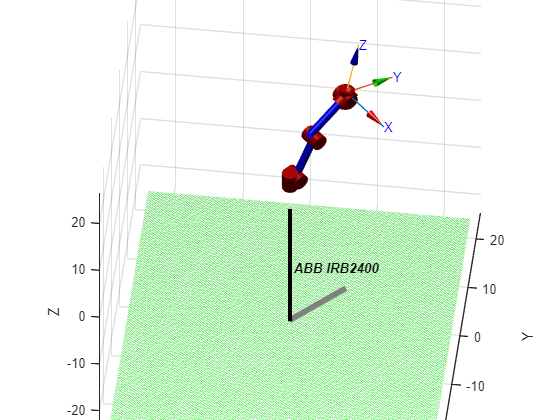

%Ejemplar - Configuración 1
T0ef=irb2400.fkine([pi/4 -pi/6 pi/3 0 pi/4 pi/2]);

irb2400.plot([pi/4 -pi/6 pi/3 0 pi/4 pi/2])
axis('auto')
view([6.8 46.2])
hold off

%CINEMÁTICA INVERSA - Configuración 1
[Ref,pef]=tr2rt(T0ef);

%Posición muñeca
pm=pef-l5*Ref(1:3,3)

pm =     7.3458
    7.3458
   17.1996


%q1
q1=atan2(pm(2),pm(1));
q1d=rad2deg(q1)

q1d = 45


pw=sqrt((pm(1)-l2*cos(q1))^2+(pm(2)-l2*sin(q1))^2+(pm(3)-l1)^2);

%alpha
ca=(l3^2+pw^2-l4^2)/(2*l3*pw);
sa1=sqrt(1-ca^2);
sa2=-sa1;
% a=atan2(sa1,ca);
a=atan2(sa2,ca);

%beta
sb=(pm(3)-l1)/pw;
cb1=sqrt(1-sb^2);
cb2=-cb1;
b=atan2(sb,cb1);
% b=atan2(sb,cb2);

%q2
q2=-pi/2+a+b;
q2d=rad2deg(q2)

q2d = -30.0000


%gamma
cg=(l3^2+l4^2-pw^2)/(2*l3*l4);
sg1=sqrt(1-cg^2);
sg2=-sg1;
g=atan2(sg1,cg);
%g=atan2(sg2,cg);

%theta
theta=atan(1.35/7.55);

%q3
q3=g-pi/2-theta;
q3d=rad2deg(q3)

q3d = 60.0000

%Orientación del efector final
R06=Ref;
[R03,~]=tr2rt(irb2400.A([1 2 3],[q1 q2 q3]));
R36=R03\R06;

%q4
q4=atan2(R36(3,3),R36(1,3));
q4d=rad2deg(q4)

q4d = -3.6726e-15

%q5
q5=atan2(cos(q4)*R36(1,3)+sin(q4)*R36(3,3),-R36(2,3));
q5d=rad2deg(q5)

q5d = 45.0000

%q6
q6=atan2(-sin(q4)*R36(1,1)+cos(q4)*R36(3,1),-sin(q4)*R36(1,2)+cos(q4)*R36(3,2));
q6d=rad2deg(q6)

q6d = 90.0000

Tci=irb2400.fkine([q1 q2 q3 q4 q5 q6])

Tci =     0.7071    0.6830    0.1830    7.5013
   -0.7071    0.6830    0.1830    7.5013
    0.0000   -0.2588    0.9659   18.0207
         0         0         0    1.0000


irb2400.plot([q1 q2 q3 q4 q5 q6])
axis('auto')
view([6.8 46.2])
hold off

Comparando la MTH obtenida asignando las coordenadas generalizadas manualmente y aquella obtenida al utilizar los resultados de cinemática inversa:

T0ef % Manual

T0ef =     0.7071    0.6830    0.1830    7.5013
   -0.7071    0.6830    0.1830    7.5013
    0.0000   -0.2588    0.9659   18.0207
         0         0         0    1.0000


Tci  % Cinemática inversa

Tci =     0.7071    0.6830    0.1830    7.5013
   -0.7071    0.6830    0.1830    7.5013
    0.0000   -0.2588    0.9659   18.0207
         0         0         0    1.0000


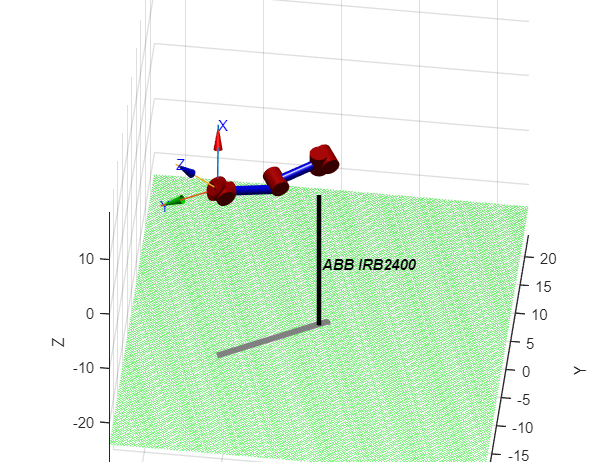

%Ejemplar - Configuración 2
T0ef=irb2400.fkine([pi/6 deg2rad(100) pi/3 pi pi/6 pi/3]);

irb2400.plot([pi/6 deg2rad(100) pi/3 pi pi/6 pi/3])
axis('auto')
view([6.8 46.2])
hold off

**Configuración 2:**

%CINEMÁTICA INVERSA - Configuración 2
[Ref,pef]=tr2rt(T0ef);

%Posición muñeca
pm=pef-l5*Ref(1:3,3)

pm =   -11.6907
   -6.7497
    6.2394


%delta
d=atan2(pm(2),pm(1));

%q1
q1=d-pi;
q1=q1+2*pi*(q1<-pi); %Evita violación de límites articulares para q1
q1d=rad2deg(q1);

pw=sqrt((pm(1)-l2*cos(q1))^2+(pm(2)-l2*sin(q1))^2+(pm(3)-l1)^2);

%alpha
ca=(l3^2+pw^2-l4^2)/(2*l3*pw);
sa1=sqrt(1-ca^2);
sa2=-sa1;
a=atan2(sa1,ca);
% a=atan2(sa2,ca);

%beta
cb=(pm(3)-l1)/pw;
sb1=sqrt(1-cb^2);
sb2=-sb1;
b=atan2(sb1,cb);
% b=atan2(sb2,cb);

%q2
q2=a+b;
q2d=rad2deg(q2);

%gamma
cg=(l3^2+l4^2-pw^2)/(2*l3*l4);
sg1=sqrt(1-cg^2);
sg2=-sg1;
g=atan2(sg1,cg);
%g=atan2(sg2,cg);

%theta
theta=atan(1.35/7.55);

%q3
q3=g-pi/2-theta;
q3d=rad2deg(q3);

%Orientación del efector final
R06=Ref;
[R03,~]=tr2rt(irb2400.A([1 2 3],[q1 q2 q3]));
R36=R03\R06;
%q4
q4=atan2(R36(3,3),R36(1,3));

%q5
q5=atan2(cos(q4)*R36(1,3)+sin(q4)*R36(3,3),-R36(2,3));

%q6
q6=atan2(-sin(q4)*R36(1,1)+cos(q4)*R36(3,1),-sin(q4)*R36(1,2)+cos(q4)*R36(3,2));

Tci=irb2400.fkine([q1 q2 q3 q4 q5 q6]);

irb2400.plot([q1 q2 q3 q4 q5 q6])
axis('auto')
view([6.8 46.2])
hold off

Comparando las MTH obtenidas asignando las coordenadas generalizadas manualmente y a partir de los resultados de cinemática inversa:

T0ef

T0ef =    -0.1013   -0.8245   -0.5567  -12.1639
    0.9415    0.1013   -0.3214   -7.0228
    0.3214   -0.5567    0.7660    6.8906
         0         0         0    1.0000


Tci

Tci =    -0.1013   -0.8245   -0.5567  -12.1639
    0.9415    0.1013   -0.3214   -7.0228
    0.3214   -0.5567    0.7660    6.8906
         0         0         0    1.0000


### 3.4. Comparación de funciones - RVC

- **ikcon: **Requiere para su funcionamiento de la función *fmincon* del Optimization Toolbox. Se puede utilizar para la cinemática inversa de robots con un número arbitrario de grados de libertad. Dado que es una función que ofrece una solución a través de métodos numéricos, el vector solución $\mathit{\mathbf{q}}$ presentará un error que se obtiene al comparar la MTH obtenida al realizar la cinemática directa utilizando $\mathit{\mathbf{q}}$ y la MTH que se deseaba obtener inicialmente. Así mismo, acepta como argumento un vector de valores iniciales a partir del cual empezará a converger hacia la solución; por tanto, la solución dependerá del vector de valores iniciales utilizado. Por último, los límites articulares definidos al crear el robot son tenidos en cuenta a la hora de encontrar la solución al problema cinemático inverso.

- **ikine:** Es utilizada con frecuencia para resolver la cinemática inversa de manipuladores de 6 o más grados de libertad. Al igual que ikcon, es una aproximación desde métodos numéricos de carácter iterativo. Ofrece un control personalizado del método numérico a emplear, al permitir seleccionar entre la traspuesta del Jacobiano o el método de pseudoinversa; así como ajustar la tolerancia en cuanto al error respecto al resultado deseado, limitar el número de iteraciones a realizar, el tamaño de paso entre iteraciones o el estado del proceso de convergencia en cada iteración. Una limitación se debe tener en cuenta al emplear esta función para manipuladores con menos de 6 grados de libertad. Dado que posición y orientación son definidas con 6 variables, para manipuladores con menos de 6 GDL, se debe emplear un *vector máscara* en el cual se indican cuáles de estos 6 parámetros se deben ignorar en el cálculo de la solución. Los parámetros a ignorar son asignados a cero, el resto a uno. La solución varía dependiendo del vector de valores iniciales empleado. Una ventaja es que este método permite obtener soluciones incluso en puntos de singularidad, aunque no tiene en cuenta los límites articulares.

- **ikine3: **Permite realizar la cinemática inversa para robots de 3GDL sin muñeca. Sus argumentos son la MTH que relaciona al efector final con la base y un argumento de configuración opcional que permite seleccionar el tipo de solución a obtener (codo arriba/abajo, brazo derecho/izquierdo). El procedimiento de solución es equivalente al de *ikine6s* sin incluir los parámetros de la muñeca.

- **ikine6s: **Esta función resuelve la cinemática inversa de forma analítica para manipuladores de 6 ejes con muñeca esférica. Al igual que *ikine3*, sus arguments son una MTH dada y, opcionalmente, una configuración para obtener una de las soluciones disponibles (codo arriba/abajo, brazo derecho/izquierdo, muñeca no rotada/rotada). Así mismo, puede trabajar con manipuladores que tengan offset en su hombro o codo, o cuya tercera articulación sea prismática (tipo Stanford). Una consideración importante es que **sólo es aplicable para manipuladores descritos con la convención DH estándar.**

- **ikine_sym:** Resuelve la cinemática inversa de forma simbólica. Su argumento principal *k* indica si se desea obtener la solución para posición en *x* y *y* (2), en los 3 ejes cartesianos (3), o la solución para posición y orientación (6). 

- **ikinem:** Resuelve la cinemática inversa de forma numérica a través de la minimización de una función error calculada a partir de la diferencia entre la pose actual y la pose objetivo. Es recomendable emplearlo para resolver manipuladores complejos, pues por defecto emplear un solver para resolver problemas no lineales (Levenberg-Marquadt), el cual es menos eficiente que las funciones analíticas descritas previamente. En ocasiones, se utiliza un vector de valores iniciales, el cual debe ser revisado con cuidado para evitar que la solución corresponda a un caso en donde el algoritmo quede estancado en un mínimo local. Así mismo, puede tener en cuenta los límites articulares.

- **ikunc:** Requiere de la función *fminunc* del Optimization Toolbox. Su funcionalidad es la misma de *ikcon*, con la salvedad de que **no tiene en cuenta los límites articulares**.

### **3.5. Selección de función - RVC**

Para el presente problema se trabaja con un robot de 6GDL para el cual es posible obtener una solución analítica, por lo cual no es necesario recurrir a funciones que empleen métodos numéricos debido a su alta exigencia a nivel computacional. Ahora, dado que el robot ha sido descrito mediante la convención DH modificado, no es posible emplear la función *ikine6s, *que sería la más adecuada para este caso, pues brinda una solución analítica para el robot de 6 GDL, la cual implica un costo computacional notablemente menor.

Según lo anterior, la función más adecuada es *ikine_sym*, la cual nos brinda una solución analítica de forma simbólica, que además reporta las distintas posibles soluciones de manera detallada. Lo anterior permite identificar con claridad todas las soluciones existentes, las cuales se podrían utilizar mediante una función que permita evaluar expresiones simbólicas con valores reales; por ejemplo, la función *subs*.